# Display pupil timecourse

## Processed contents

- Thresholding Deep Lab Cut (DLC) estimated coordinates with likelihood. Frames with low likelihood are assumed to be missing value.

- Upsampling the estimated coordinates from about 30 Hz to 10 Hz

- Plotting input features

## Points estimated by DLC

- PRxy: pupil rostral

- PCxy: pupil caudal

- UEMxy: upper eye margin

- LEMxy: lower eye margin

## Features

- PD: pupil diameter

- PL: pupil center location

- PV: pupil velocity

- EO: eyelid opening

clearvars;

## Set variables

Flag.saveData = 1;
Flag.saveFigs = 1;

directory_rawdata = '../../Data/SNT267/20200806';
filename_video = 'SNT267_0806.mp4';
filename_PDcsv = 'SNT267_0806DLC_resnet50_DLCJul19shuffle1_280000.csv';
filename_timestamp = 'video_01.txt';

Col.PR = 'b';%[0 0.4470 0.7410];% b
Col.PC = [0.3010 0.7450 0.9330];% c
Col.UEM = [0.9290 0.6940 0.1250];% y
Col.LEM = [0.6350 0.0780 0.1840];%

## Set parameters

fs_resampled = 10;% resample from ~30 Hz to 10 Hz
TH_likelihood = 0.99;
PD_range = 0.001;% Pupil diameter
EO_range = 0.001;% Eyelid opening.

## Load timestamps and DLC-location data

### Timestamp timecourse

fid = fopen(fullfile(directory_rawdata, filename_timestamp));
ts_temp = textscan(fid, '%f', 'CommentStyle', '%');
fclose(fid);
Timestamps = milliseconds(ts_temp{1});

disp(['TSdata size: ', num2str(length(Timestamps))])

TSdata size: 306574


disp(['TSdata: ', num2str(milliseconds(Timestamps(1:5)')), ' ...'])

TSdata: 0   34   66   99  134 ...


clear ts_temp

### Pupil data by DLC

%% get only headers
count_headerrows_temp = 3;
fid = fopen(fullfile(directory_rawdata, filename_PDcsv));
lineheaders_temp = cell(count_headerrows_temp,1);
for ii=1:count_headerrows_temp
    lineheaders_temp{ii,1} = strsplit(fgetl(fid), ',')';
end
fclose(fid);

%% join second and third headers for variable names
count_variables_temp = length(lineheaders_temp{1});
varnames_temp = strings(1,count_variables_temp);
for ii = 1:count_variables_temp
    varnames_temp(ii) = string([lineheaders_temp{2}{ii}, '_', lineheaders_temp{3}{ii}]);
end

%% load values: PR_x ...
TablePupil = readtable(fullfile(directory_rawdata, filename_PDcsv), ...
    'FileType', 'text', 'HeaderLines', count_headerrows_temp);

%% set variable names
TablePupil.Properties.VariableNames = varnames_temp;
TablePupil = addvars(TablePupil, Timestamps, 'Before', varnames_temp{2})

TablePupil = 306574×14 table
    bodyparts_coords    Timestamps     PR_x      PR_y     PR_likelihood     PC_x      PC_y     PC_likelihood    UEM_x     UEM_y     UEM_likelihood    LEM_x     LEM_y     LEM_likelihood
    ________________    __________    ______    ______    _____________    ______    ______    _____________    ______    ______    ______________    ______    ______    ______________

            0                0 秒      82.315    142.88          1           151.1    129.39          1          114.47    102.31          1           128.92    165.25          1       
            1            0.034 秒      82.084    142.08          1          151.49    128.64          1          114.92    102.16          1           129.01    165.16          1       
            2            0.066 秒      82.339    142.44          1          151.06    129.35          1          114.54    102.32          1           129.12    165.23          1       
            3            0.099 秒      81.939 


clear count_headerrows_temp lineheaders_temp count_variables_temp varnames_temp

## Process

### Discard points with low likelihood

LHmat = [TablePupil.PR_likelihood,...
    TablePupil.PC_likelihood,...
    TablePupil.UEM_likelihood,...
    TablePupil.LEM_likelihood];% original likelihood timecourse 変数名の変更あり


PosiTH = [TablePupil.PR_x,...
    TablePupil.PC_x,...
    TablePupil.UEM_x,...
    TablePupil.UEM_x,...
    TablePupil.PR_y,...
    TablePupil.PC_y,...
    TablePupil.UEM_y,...
    TablePupil.LEM_y];
PosiTH([LHmat, LHmat] < TH_likelihood) = NaN;% THresholded Position timecourse [PR, PC, UEM, LEM]

### Linearly interpolating missing values before resampling

[PosiTH_fil, TF_PosiTH] = fillmissing(PosiTH, 'linear', 'SamplePoints', TablePupil.Timestamps);
LHPosi = [LHmat, PosiTH_fil];% Likelihood-Position matrix: 4 columns of Likelihoods of PR, PC, UEM,and LEM and  4 columns of XY cordinates of each DLC estimated position.
[LHPosi_resample, ty] = resample(LHPosi, seconds(TablePupil.Timestamps), fs_resampled);% SR 10 Hz, time in sec

TablePupilResampled = [table(seconds(ty), 'VariableNames', {'Timestamps'}),...
    array2table(LHPosi_resample, 'VariableNames',{'LH_PR', 'LH_PC', 'LH_UEM', 'LH_LEM', 'PRx', 'PCx', 'UEMx', 'LEMx', 'PRy', 'PCy', 'UEMy', 'LEMy'})];

### Calculate features: PD, PL, PV, EO

- PD: pupil diameter; Distance between PR and RC

- PL: pupil location; [mean(PRx, PCx), mean(PRy, PCy)]

- PV: pupil velocity; Diff(PL)

- EO: eyelid opening; Distance between UEM and LEM

#### Calcutale naive features.

PD = ((TablePupilResampled.PRx - TablePupilResampled.PCx).^2 + (TablePupilResampled.PRy - TablePupilResampled.PCy).^2).^0.5;
PLori = [mean([TablePupilResampled.PRx, TablePupilResampled.PCx], 2), mean([TablePupilResampled.PRy, TablePupilResampled.PCy], 2)];
PL = PLori - repmat(mean(PLori), length(PLori),1);
PV = (diff([PL(:,1);PL(end,1)]).^2 + diff([PL(:,2);PL(end,2)]).^2).^0.5;
EO = ((TablePupilResampled.UEMx - TablePupilResampled.LEMx).^2 + (TablePupilResampled.UEMy - TablePupilResampled.LEMy).^2).^0.5;

#### Calculate EO ratio and detect blinks (signal has 10Hz sampling rate)

caution : chronux also consists of findpeaks function @ \chronux_2_12\spectral_analysis\continuous\findpeaks.m

EO_sorted = sort(EO, 'descend');
EO_max = mean(EO_sorted(1:ceil(length(EO_sorted)*EO_range)));
EO_min = mean(EO_sorted(end - ceil(length(EO_sorted)*EO_range):end));

EO_ratio = rescale(EO, 0, 1, "InputMax", EO_max, "InputMin", EO_min);
[EO_pks, EO_locs, EO_w, EO_p] = findpeaks(-EO_ratio,...
    'MinPeakProminence', 0.3, 'MaxPeakWidth', 150);%'MinPeakDistance', 20, 'MinPeakWidth', 3);
EO_pks = -EO_pks;

#### Obtain PD w/o blink, and Calculate PD ratio.

% correct PD with blink to missing value, and interpolate it.

Idx_blink_cell = arrayfun(@colon, EO_locs-round(EO_w), EO_locs+round(EO_w), 'Uniform', false);
Idx_blink = [Idx_blink_cell{:}]';
Idx_blink(Idx_blink <= 0) = 1;
Idx_blink(Idx_blink > length(ty)) = length(ty);

PD_with_blink_as_NaN = PD;
PD_with_blink_as_NaN(Idx_blink) = NaN;

% fillmissing with pchip was embrased as a method of interpolation.
% pchip: piecewise cubic Hermite interpolating polynomial
PD_wo_blink = fillmissing(PD_with_blink_as_NaN, 'pchip');

% Calculate PD ratio accounting for blink.
PD_sorted = sort(PD_wo_blink, 'descend');
PD_max = mean(PD_sorted(1:ceil(length(PD_sorted)*PD_range)));
PD_min = mean(PD_sorted(end - ceil(length(PD_sorted)*PD_range):end));

PD_ratio = rescale(PD_wo_blink, 0, 1, "InputMax", PD_max, "InputMin", PD_min);

## Plot

### Timecourse Raw data

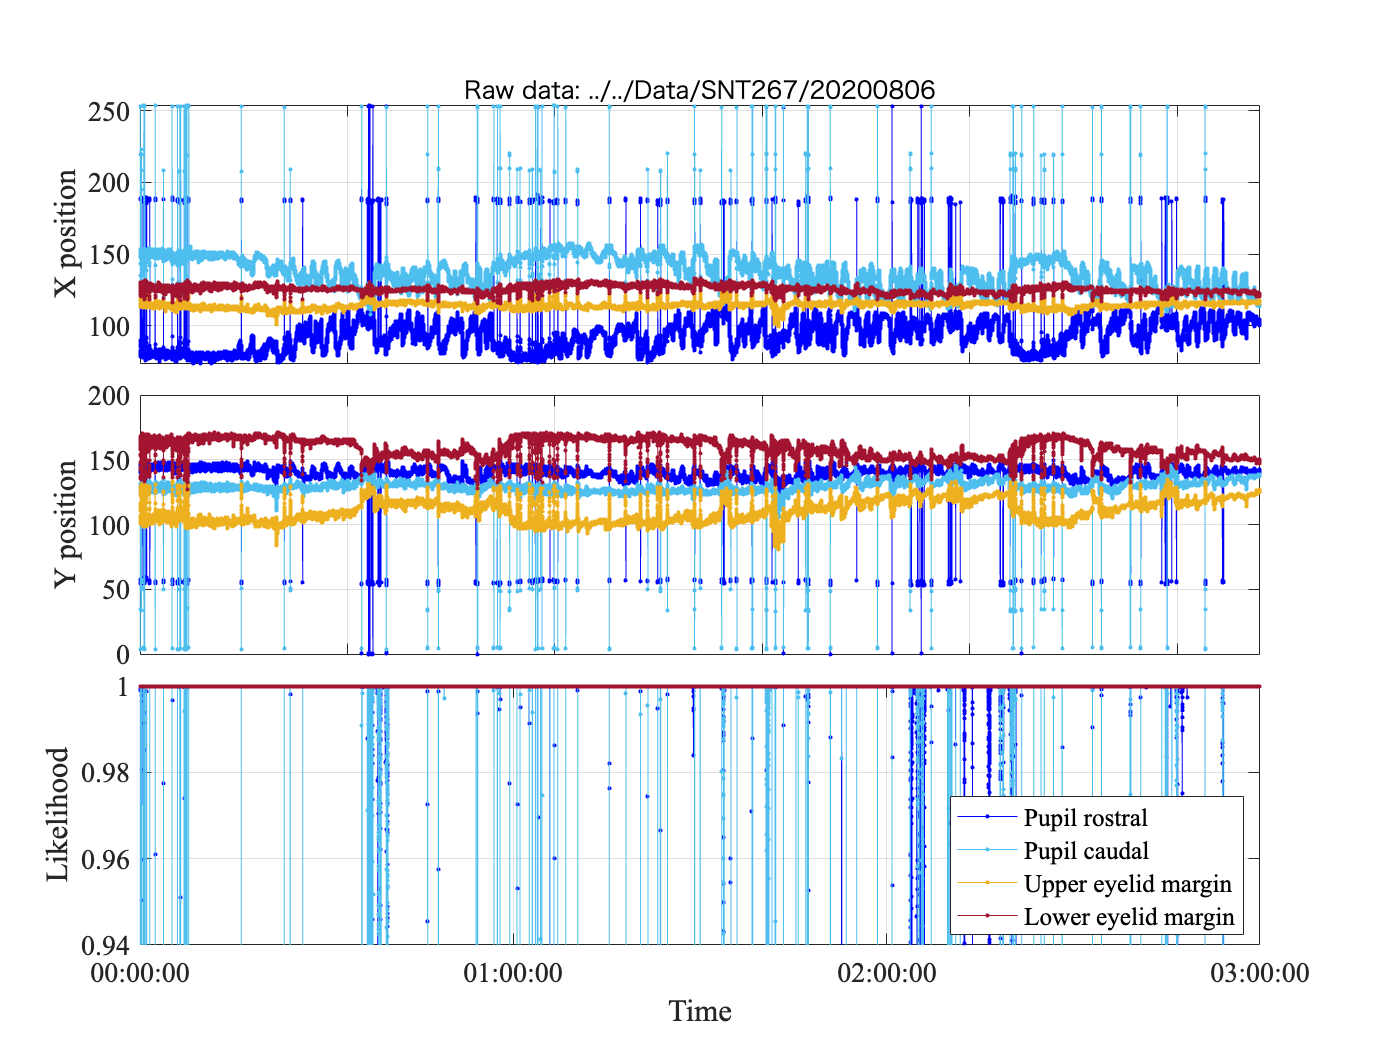

h.fig_PRxL = figure;

h.ax_raw_X = subaxis(3,1,1,'SpacingVertical', 0.03);
setFig(struct('fontsize_title', 12, 'fontsize_axis', 14)); hold on;
h.plot_raw_X = plot(TablePupil.Timestamps, [TablePupil.PR_x, TablePupil.PC_x, TablePupil.UEM_x, TablePupil.LEM_x], 'marker', '.');
set(h.plot_raw_X, {'color'}, {Col.PR; Col.PC; Col.UEM; Col.LEM})
ylabel(sprintf('X position'))
title(sprintf('Raw data: %s', directory_rawdata), 'Interpreter','none')

h.ax_raw_Y = subaxis(3,1,2,'SpacingVertical', 0.03);
setFig(struct('fontsize_title', 12, 'fontsize_axis', 14)); hold on;
h.plot_raw_Y = plot(TablePupil.Timestamps, [TablePupil.PR_y, TablePupil.PC_y, TablePupil.UEM_y, TablePupil.LEM_y], 'marker', '.');
set(h.plot_raw_Y, {'color'}, {Col.PR; Col.PC; Col.UEM; Col.LEM})
ylabel('Y position')

h.ax_raw_LH = subaxis(3,1,3, 'SpacingVertical', 0.03);
setFig(struct('fontsize_title', 12, 'fontsize_axis', 14)); hold on;
h.plot_raw_LH = plot(TablePupil.Timestamps,...
    [TablePupil.PR_likelihood, TablePupil.PC_likelihood, TablePupil.UEM_likelihood, TablePupil.LEM_likelihood], 'marker', '.');
set(h.plot_raw_LH, {'color'}, {Col.PR; Col.PC; Col.UEM; Col.LEM})
ylabel(sprintf('Likelihood'));
ylim([TH_likelihood-0.05 1])
xtickformat('hh:mm:ss');
xlabel('Time')
legend({'Pupil rostral', 'Pupil caudal', 'Upper eyelid margin', 'Lower eyelid margin'}, 'Location', 'southeast')

set([h.ax_raw_X, h.ax_raw_Y], 'XTickLabel', []);
set([h.ax_raw_X, h.ax_raw_Y, h.ax_raw_LH], 'XGrid', 'on', 'YGrid', 'on');
linkaxes([h.ax_raw_X, h.ax_raw_Y, h.ax_raw_LH], 'x');
xlim([0 TablePupil.Timestamps(end)])

### Hist likelihood

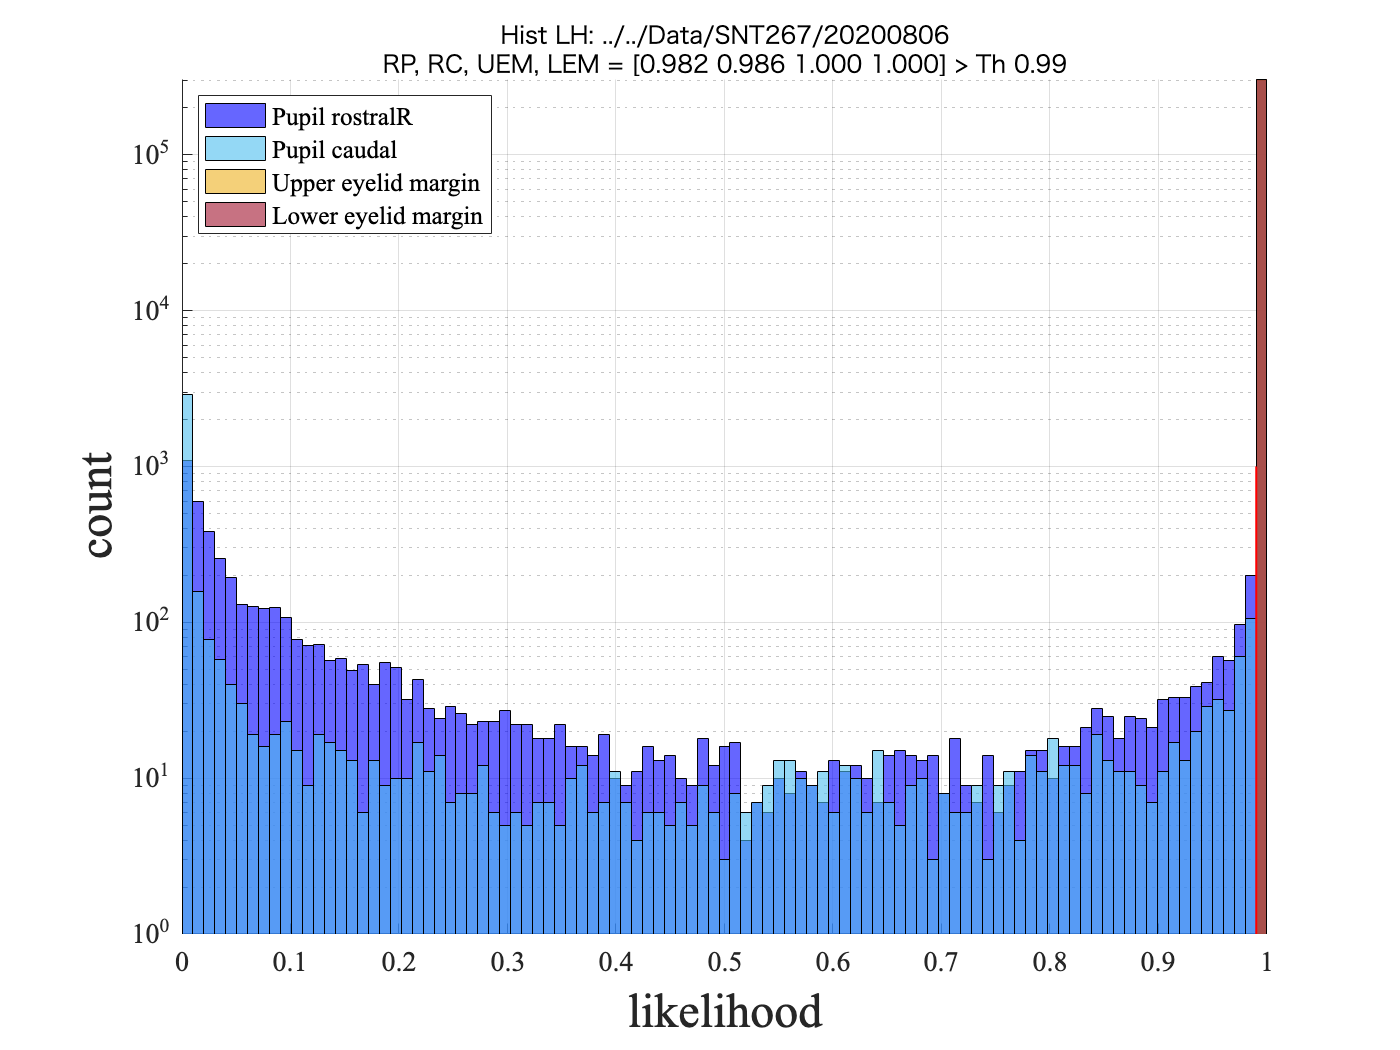

LHratio = sum([TablePupil.PR_likelihood, TablePupil.PC_likelihood, TablePupil.UEM_likelihood, TablePupil.LEM_likelihood]...
    > TH_likelihood)/size(TablePupil.PR_likelihood,1);

edges = linspace(0,1,100);
h.fig_histL = figure; hold on;
histogram(TablePupil.PR_likelihood, edges, "FaceColor", Col.PR, 'DisplayName', 'Pupil rostralR');
histogram(TablePupil.PC_likelihood, edges, "FaceColor", Col.PC, 'DisplayName', 'Pupil caudal');
histogram(TablePupil.UEM_likelihood, edges, "FaceColor", Col.UEM, 'DisplayName', 'Upper eyelid margin');
histogram(TablePupil.LEM_likelihood, edges, "FaceColor", Col.LEM, 'DisplayName','Lower eyelid margin');
line([TH_likelihood TH_likelihood], [1 1000], 'Color','r', 'HandleVisibility',"off", 'linewidth', 1)
set(gca, 'YScale', 'log')
legend('Location', 'northwest')
grid on;

setFig(struct('fontsize_title', 12, 'fontsize_axis', 14), 'likelihood', 'count', [], []);
title(sprintf("Hist LH: %s\nRP, RC, UEM, LEM = [%2.3f %2.3f %2.3f %2.3f] > Th %2.2f",...
    directory_rawdata, LHratio, TH_likelihood), 'Interpreter','none')
axis tight; grid on, xlim([0 1])

### Timecourse Resampled

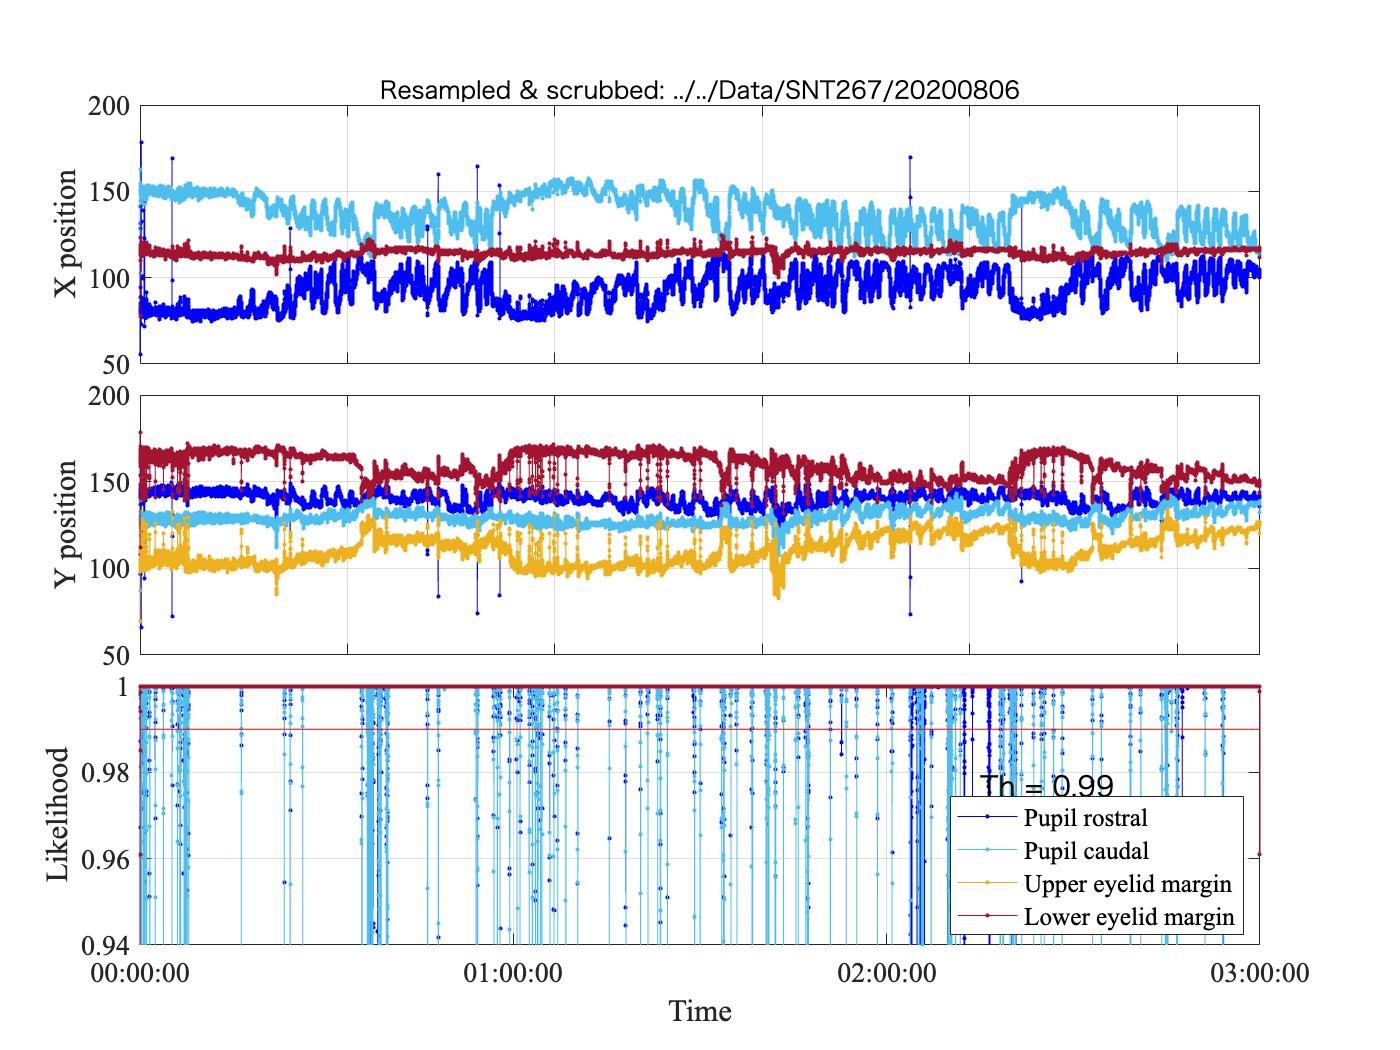

h.fig_LHPosi = figure;

h.ax_LHPosi_X = subaxis(3,1,1,'SpacingVertical', 0.03);
setFig(struct('fontsize_title', 12, 'fontsize_axis', 14)); hold on;
h.plot_LHPosi_X = plot(seconds(ty), LHPosi_resample(:,5:8), 'marker', '.');
set(h.plot_LHPosi_X, {'color'}, {Col.PR; Col.PC; Col.UEM; Col.LEM})
ylabel(sprintf('X position'))
title(sprintf('Resampled & scrubbed: %s', directory_rawdata), 'Interpreter','none')


h.ax_LHPosi_Y = subaxis(3,1,2,'SpacingVertical', 0.03);
setFig(struct('fontsize_title', 12, 'fontsize_axis', 14)); hold on;
h.plot_LHPosi_Y = plot(seconds(ty), LHPosi_resample(:,9:12), 'marker', '.');
set(h.plot_LHPosi_Y, {'Color'}, {Col.PR; Col.PC; Col.UEM; Col.LEM})
ylabel('Y position')

TH_likelihood_bottomRange = 0.05;
h.ax_LHPosi_LH = subaxis(3,1,3, 'SpacingVertical', 0.03);
setFig(struct('fontsize_title', 12, 'fontsize_axis', 14)); hold on;
h.plot_LHPosi_LH = plot(seconds(ty), LHPosi_resample(:,1:4), 'marker', '.');
text(seconds(ty(round(length(ty)*3/4))), TH_likelihood-TH_likelihood_bottomRange/4, ...
    sprintf('Th = %2.2f', TH_likelihood), 'FontSize', 14)
line([seconds(ty(1)), seconds(ty(end))], [TH_likelihood TH_likelihood], 'Color','r', 'HandleVisibility',"off")
set(h.plot_LHPosi_LH, {'Color'}, {Col.PR; Col.PC; Col.UEM; Col.LEM});
ylabel(sprintf('Likelihood'));
ylim([TH_likelihood-TH_likelihood_bottomRange 1])

xlabel('Time')
xtickformat('hh:mm:ss');
legend({'Pupil rostral', 'Pupil caudal', 'Upper eyelid margin', 'Lower eyelid margin'},'Location', 'southeast');

set([h.ax_LHPosi_X, h.ax_LHPosi_Y], 'XTickLabel', []);
set([h.ax_LHPosi_X, h.ax_LHPosi_Y, h.ax_LHPosi_LH], 'XGrid', 'on', 'YGrid', 'on');
linkaxes([h.ax_LHPosi_X, h.ax_LHPosi_Y, h.ax_LHPosi_LH], 'x');
xlim([0 TablePupil.Timestamps(end)])

### Timecourse Features: PD, PLx, PLy, PV, EO

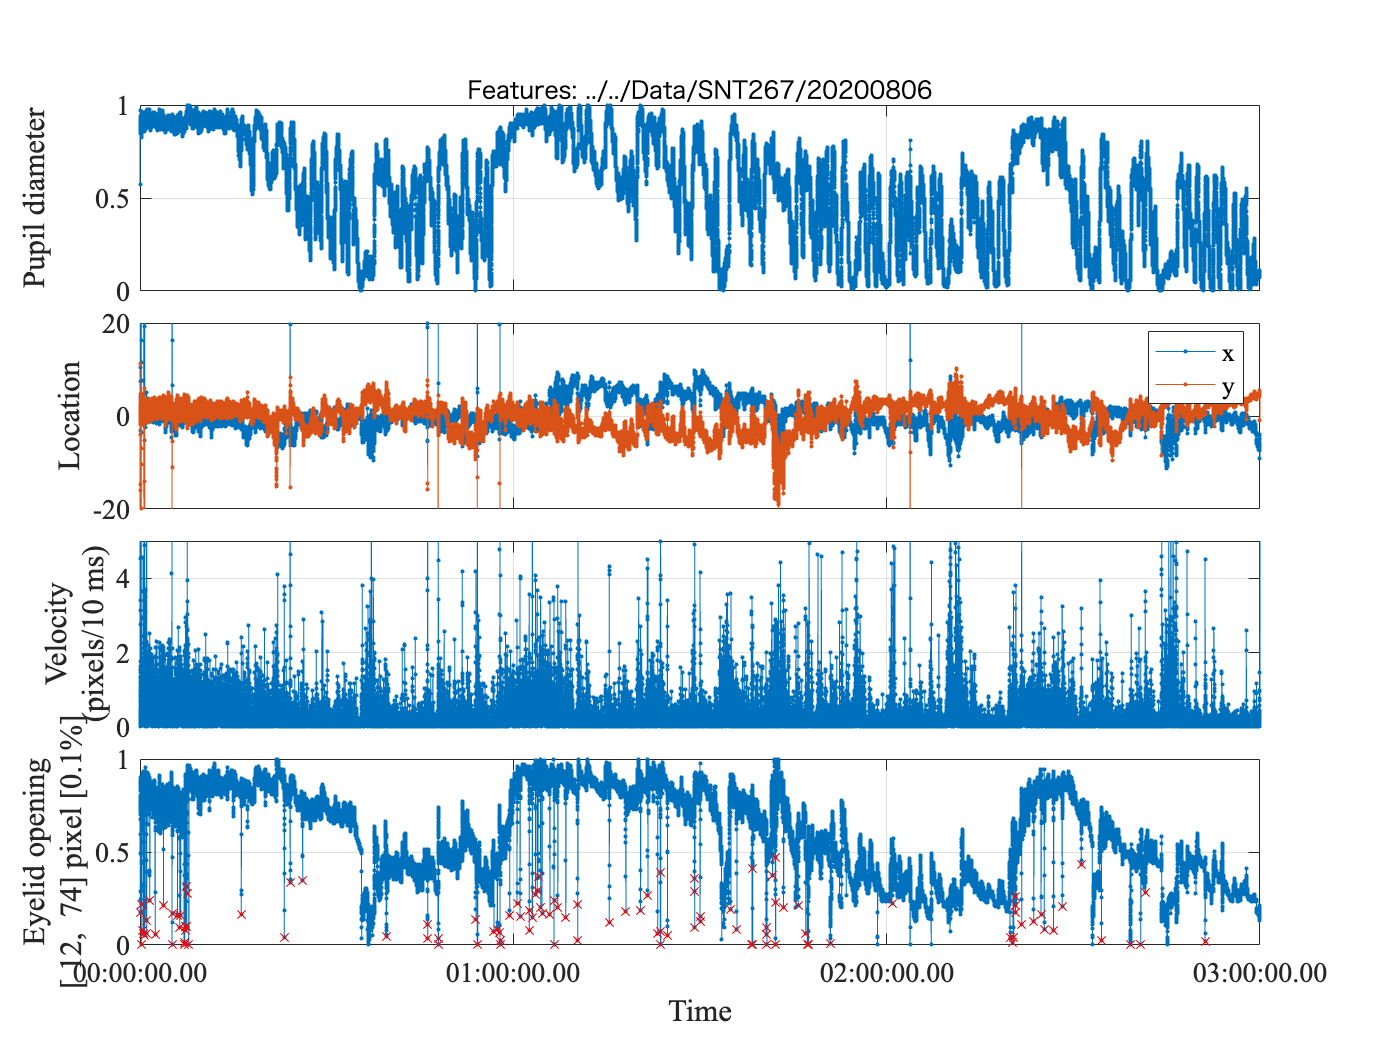

h.fig_features = figure;% plotting in 10 Hz sampling rate

h.ax_PD = subaxis(4,1,1, 'SpacingVertical', 0.03);
setFig(struct('fontsize_title', 12, 'fontsize_axis', 14)); hold on;
h.plot_PD = plot(seconds(ty), PD_ratio, 'marker', '.');
ylabel(sprintf('Pupil diameter\n%[3.0f, %3.0f] pixel [%2.1f%%]', PD_min, PD_max, PD_range * 100));
title(sprintf('Features: %s', directory_rawdata), 'Interpreter', 'none');
xtickformat('hh:mm:ss.SS')

h.ax_PL = subaxis(4,1,2, 'SpacingVertical', 0.03);
setFig(struct('fontsize_title', 12, 'fontsize_axis', 14)); hold on;
h.plot_PLx = plot(seconds(ty), PL(:,1), 'marker', '.', 'DisplayName', 'Pupil location x');
h.plot_PLy = plot(seconds(ty), PL(:,2), 'marker', '.', 'DisplayName', 'Pupil location y');
ylabel('Location')
ylim([-20 20])
legend({'x', 'y'})
xtickformat('hh:mm:ss.SS')

h.ax_PV = subaxis(4,1,3, 'SpacingVertical', 0.03);
setFig(struct('fontsize_title', 12, 'fontsize_axis', 14)); hold on;
h.plot_PV = plot(seconds(ty), PV, 'marker', '.', 'DisplayName', 'Pupil velocity');
ylabel(sprintf('Velocity\n(pixels/10 ms)'));
ylim([0 5]);
xtickformat('hh:mm:ss.SS')

h.ax_EO = subaxis(4,1,4, 'SpacingVertical', 0.03);
setFig(struct('fontsize_title', 12, 'fontsize_axis', 14)); hold on;
h.plot_EO = plot(seconds(ty), EO_ratio, 'marker', '.', 'DisplayName', 'Eye opening');
plot(seconds(ty(EO_locs)), EO_pks, 'xr')
ylabel(sprintf('Eyelid opening\n[%3.0f, %3.0f] pixel [%2.1f%%]', EO_min, EO_max, EO_range * 100));
xlabel('Time')
xtickformat('hh:mm:ss.SS')

set([h.ax_PD, h.ax_PL, h.ax_PV], 'XTickLabel',[]);
set([h.ax_PD, h.ax_PL, h.ax_PV, h.ax_EO], 'XGrid', 'on', 'YGrid', 'on');
linkaxes([h.ax_PD, h.ax_PL, h.ax_PV, h.ax_EO], 'x');


xlim([0 seconds(ty(end))])

## Timecourse Features with video timing: PD, PLx, PLy, PV, EO

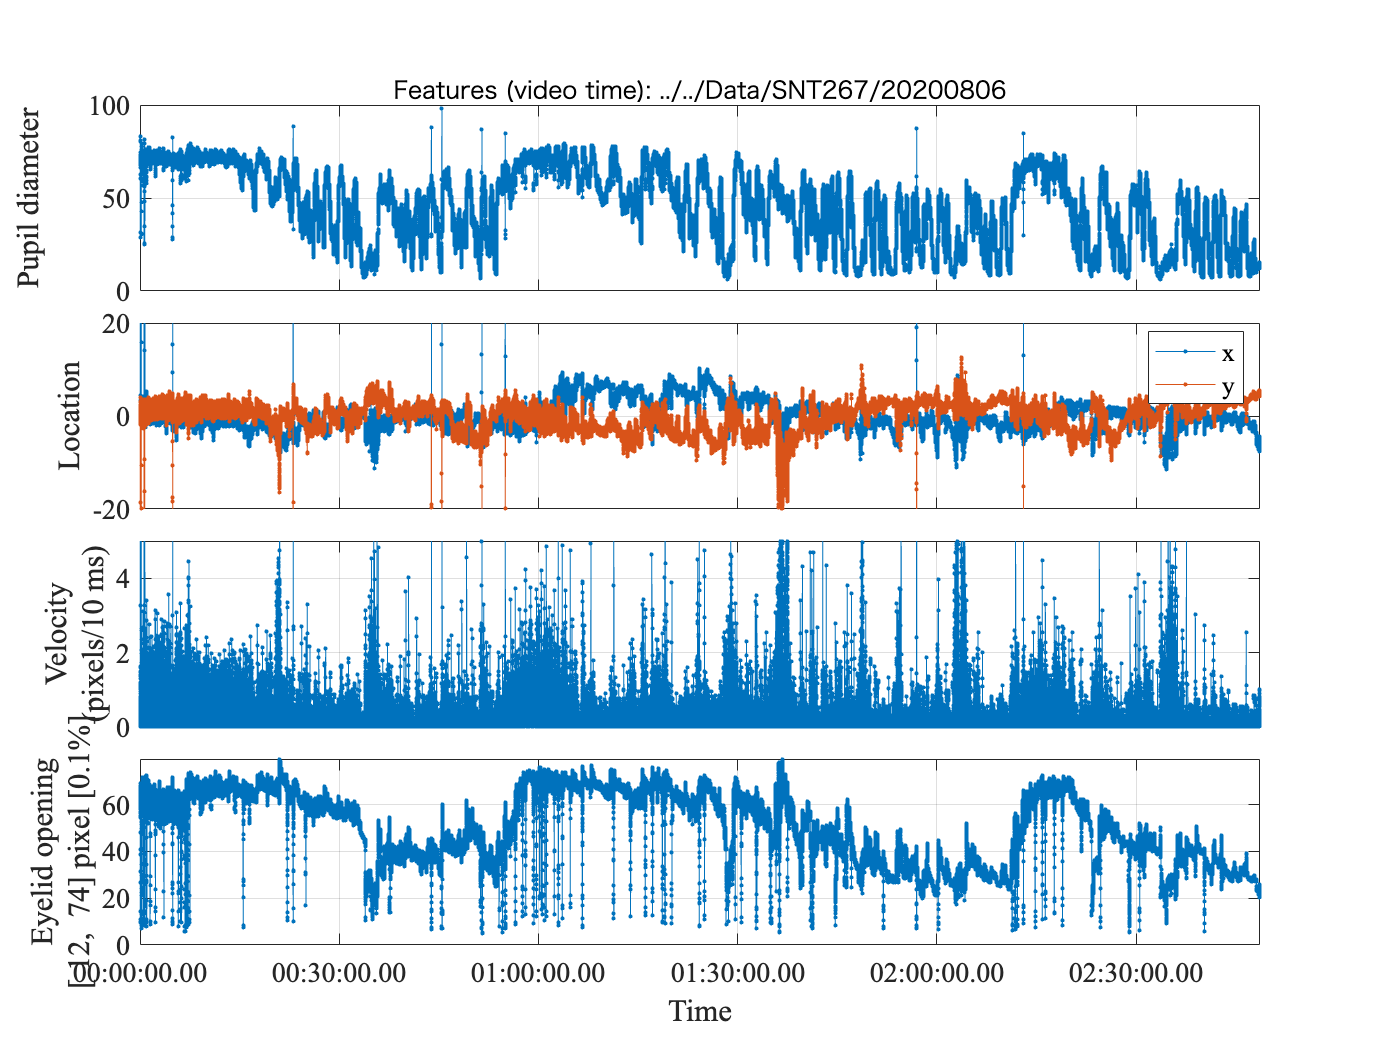

% LHposi:
% % Likelihood-Position matrix: 4 columns of Likelihoods of PR, PC, UEM,and LEM and  4 columns of XY cordinates of each DLC estimated position.
tt_video = [1:length(LHPosi)]/30.3;% sec
PD_video = ((LHPosi(:,5) - LHPosi(:,6)).^2 + (LHPosi(:,9) - LHPosi(:,10)).^2).^0.5;
PLori_video = [mean(LHPosi(:,5:6),2), mean(LHPosi(:,9:10),2)];
PL_video = PLori_video - repmat(mean(PLori_video), length(PLori_video), 1);
PV_video = (diff([PL_video(:,1); PL_video(end,1)]).^2 + diff([PL_video(:,2);PL_video(end,2)]).^2).^0.5;
EO_video = ((TablePupil.UEM_x - TablePupil.LEM_x).^2 ...
    + (TablePupil.UEM_y - TablePupil.LEM_y).^2).^0.5;

h.fig_features_videoTime = figure;% plotting in 100 Hz sampling rate

h.ax_PD_videoTime = subaxis(4,1,1, 'SpacingVertical', 0.03);
setFig(struct('fontsize_title', 12, 'fontsize_axis', 14)); hold on;
h.plot_PD_videoTime = plot(seconds(tt_video), PD_video, 'marker', '.');
ylabel(sprintf('Pupil diameter\n%[3.0f, %3.0f] pixel [%2.1f%%]', PD_min, PD_max, PD_range * 100));
title(sprintf('Features (video time): %s', directory_rawdata), 'Interpreter', 'none');
xtickformat('hh:mm:ss.SS')

h.ax_PL_videoTime = subaxis(4,1,2, 'SpacingVertical', 0.03);
setFig(struct('fontsize_title', 12, 'fontsize_axis', 14)); hold on;
h.plot_PLx = plot(seconds(tt_video), PL_video(:,1), 'marker', '.', 'DisplayName', 'Pupil location x');
h.plot_PLy = plot(seconds(tt_video), PL_video(:,2), 'marker', '.', 'DisplayName', 'Pupil location y');
ylabel('Location')
ylim([-20 20])
legend({'x', 'y'})
xtickformat('hh:mm:ss.SS')

h.ax_PV_videoTime = subaxis(4,1,3, 'SpacingVertical', 0.03);
setFig(struct('fontsize_title', 12, 'fontsize_axis', 14)); hold on;
h.plot_PV = plot(seconds(tt_video), PV_video, 'marker', '.', 'DisplayName', 'Pupil velocity');
ylabel(sprintf('Velocity\n(pixels/10 ms)'));
ylim([0 5]);
xtickformat('hh:mm:ss.SS')

h.ax_EO_videoTime = subaxis(4,1,4, 'SpacingVertical', 0.03);
setFig(struct('fontsize_title', 12, 'fontsize_axis', 14)); hold on;
h.plot_EO_videoTime = plot(seconds(tt_video), EO_video, 'marker', '.', 'DisplayName', 'Eye opening');
%plot(seconds(tt_video(EO_locs_video)), EO_pks, 'xr')
ylabel(sprintf('Eyelid opening\n[%3.0f, %3.0f] pixel [%2.1f%%]', EO_min, EO_max, EO_range * 100));
xlabel('Time')
xtickformat('hh:mm:ss.SS')

set([h.ax_PD_videoTime, h.ax_PL_videoTime, h.ax_PV_videoTime], 'XTickLabel',[]);
set([h.ax_PD_videoTime, h.ax_PL_videoTime, h.ax_PV_videoTime, h.ax_EO_videoTime], 'XGrid', 'on', 'YGrid', 'on');
linkaxes([h.ax_PD_videoTime, h.ax_PL_videoTime, h.ax_PV_videoTime, h.ax_EO_videoTime], 'x');

xlim([0 seconds(tt_video(end))])

if Flag.saveData
    writematrix(ty, fullfile(directory_rawdata, "pupil", sprintf("time_pupil%dHz.csv", fs_resampled)));
    writematrix(PD_ratio, fullfile(directory_rawdata, "pupil", sprintf("PD_ratio%dHz.csv", fs_resampled)));
    writematrix(PL, fullfile(directory_rawdata, "pupil", sprintf("PupilLocation%dHz.csv", fs_resampled)));
    writematrix(PV, fullfile(directory_rawdata, "pupil", sprintf("Pupil_velocity%dHz.csv", fs_resampled)));
    writematrix(EO_ratio, fullfile(directory_rawdata, "pupil", sprintf("EyeOpening_ratio%dHz.csv", fs_resampled)));
end
if Flag.saveFigs
    print(h.fig_LHPosi, '-r300', '-dpng', fullfile(replace(directory_rawdata, "Data", "Figure"), "resampled_pupil_trace.png"));
    print(h.fig_features_videoTime, '-r300', '-dpng', fullfile(replace(directory_rawdata, "Data", "Figure"), "features_videoTime.png"));

end